# 1.2.17. Цифровая обработка сигналов в MATLAB

**Лекция**

Когда мы говорим о задачах цифровой обработки сигналов (ЦОС), чаще всего упоминаются анализ сигнала во временной и частотной областях, а также фильтрация. Под анализом в частотной области подразумевается вычисление энергетического спектра сигнала (или его спектральной плотности мощности). График энергетического спектра или спектральной плотности мощности (СПМ) показывает, на каких частотах сигнал колеблется с большей амплитудой, а на каких - с меньшей. Отдельные синусоидальные колебания на спектре принимают вид линий - положение линии на оси х указывает на частоту колебвания синусоиды, а величина, или её значение на оси у - амплитуду. Спектр шумоподобного сигнала часто занимает весь рассматриваемый диапазон частот, и на нём нельзя выделить явные пики или спады. На рисунке показан график спектральной плотности мощности смеси синусоидального сигнала и шума. Мы явно наблюдаем пик на фоне так называемого "шумового дна".

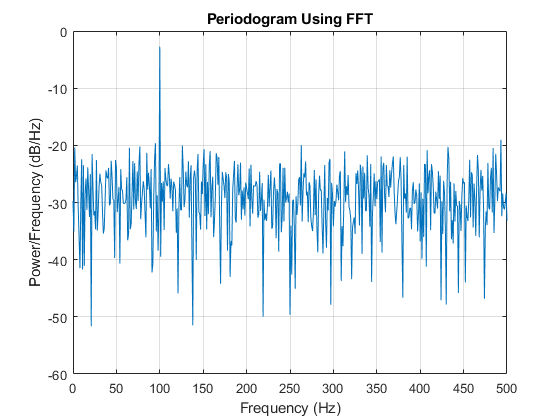

Спектр сигнала позволяет проще оценить вклад тех или иных частотных компонент сигнала, определить, какие из них являются для нас полезными, а какие - шумом или помехой. После этого можно разработать подходящий цифровой фильтр, который бы пропускал полезный сигнал и подавлял нежелательные спектральные компоненты.

К примеру, если мы знаем, что полезный сигнал сосредоточен в левой части спектра, то есть в области низких частот, мы можем использовать фильтр нижних частот, который ослабит уровень спектральных компонент выше определённой частоты - частоты среза.

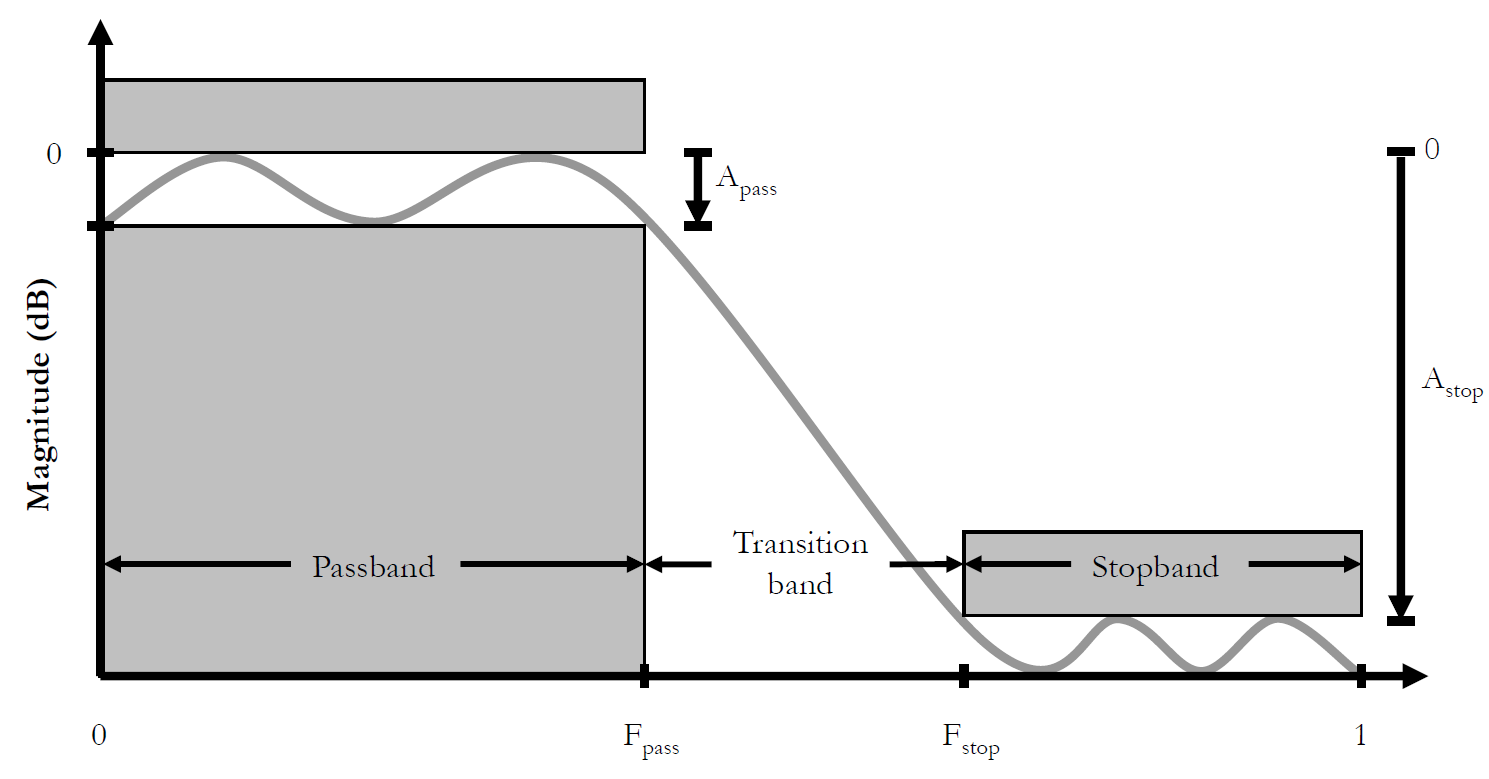

На рисунке представлена аплитудо-частотная характеристика (АЧХ) фильтра нижних частот (ФНЧ). Эта характеристика показывает зависимость усиления цепи в зависимости от частоты проходящего через неё сигнала. АЧХ наряду с фазо-частотной характеристикой (ФЧХ) характеризуют поведение фильтра, то есть его влияние на входной сигнал. В данной лекции мы не будем затрагивать вопросы искажения фазы, поэтому фильтры мы будем характеризовать именно параметрами их АЧХ.

Рассмотрим эти параметры на примере ФНЧ. У такого фильтра есть полоса пропускания, ограниченная частотой среза Fpass. В пределах этой частоты фильтр должен (в идеале) пропускать входной сигнал без искажений. На практике же большинство фильтров немного изменяют, то есть усиливают или ослабляют, различные частотные компоненты сигнала в полосе пропускания. Уровень отклонения коэффициента усиления в полосе пропускания от единицы называется коэффициентом пульсаций фильтра Apass, и измеряется он в дБ. 

Также у фильтра есть полоса заграждения, начинающаяся в случае ФНЧ после частоты Fstop. В этой полосе фильтр должен гарантировать подавление входного сигнала на величину не менее Astop (коэффициент аттенюации, измеряется в дБ). 

Между ними расположенна так называемая переходная полоса. Крутизна перехода от полосы пропускания к полосе заграждения зависит от порядка фильтра. Более "прямоугольная"  характеристика предпочтительна по сравнению с более "пологой", но фильтры большого порядка сложно реализовать на аппаратных платформах, поэтому при разработке часто приходится искать копромисс между порядком фильтра и качеством его характеристики.

Полезный сигнал может быть расположен в правой части спектра, и тогда нам потребуется фильтр верхних частот (ФВЧ), или же сигнал может занимать определённую полосу - в этом случае нам поможет полосно-пропускающий фильтр. АЧХ таких фильтров представлены ниже.

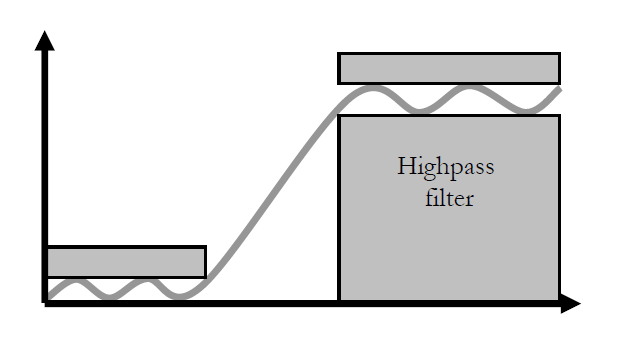   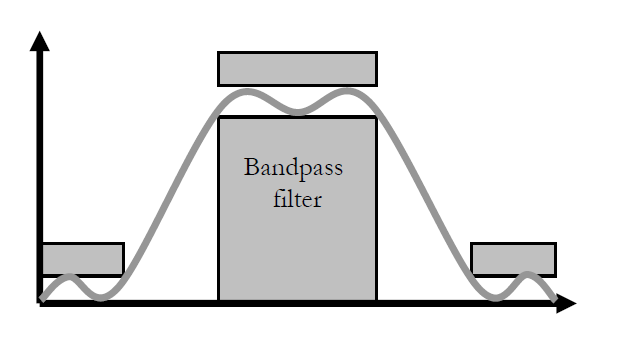

В данной лекции мы рассмотрим пример анализа и обработки зашумлённого аудио-сигнала. Мы визуализируем его во временной и частотной областях, а также выделим полезный сигнал (мелодию) из смеси "сигнал+шум" с помощью цифрового фильтра.

## Импорт аудио-файла в MATLAB

Считаем аудио-файл *intro_noise.wav* в рабочее пространство командой *audioread*. Данная функция принимает на свой вход имя аудио-файла. Отсчёты сигнала поместим в переменную *x*, а скалярное значение частоты дискретизации - в переменную *fs*.

[x,fs] = audioread('intro_noise.wav');

Прослушаем импортированный сигнал командой *sound*.

sound(x,fs);

## Приложение Signal Analyzer

Воспользуемся приложением **Signal Analyzer** для визуализации сигнала во временной и частотной областях. 

signalAnalyzer;

Для отображения сигнала во временной области достаточно просто перетащить любой из доступных векторов рабочего пространства в область анализируемы сигналов поставить напротив имени сигнала галочку.

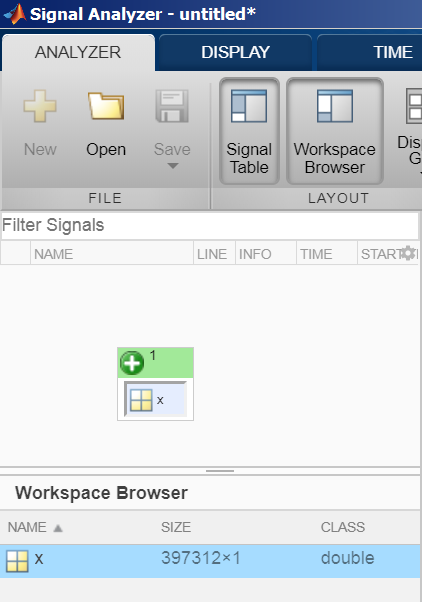                    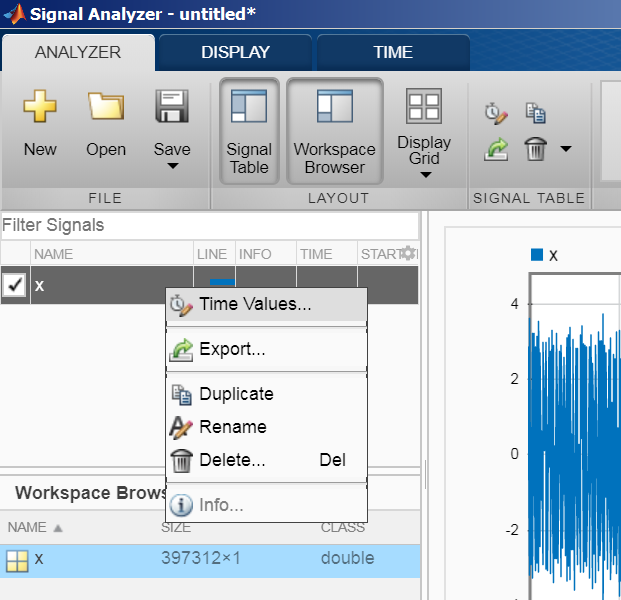

Сигналу можно указать временные значения либо в явном виде (передать вектор значений времени), либо указав частоту дискретизации, период дискретзации, или же не указывать ничего и оперировать индексами отсчётов в векторе. Укажем для нашего вектора *х* частоту дискретизации *fs*.

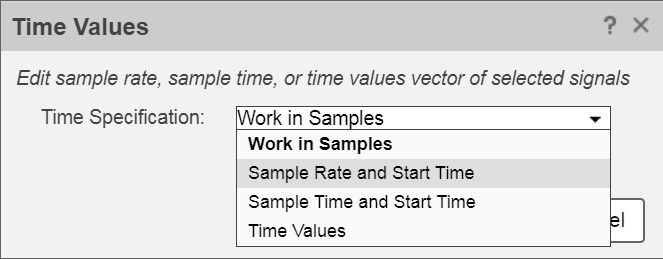             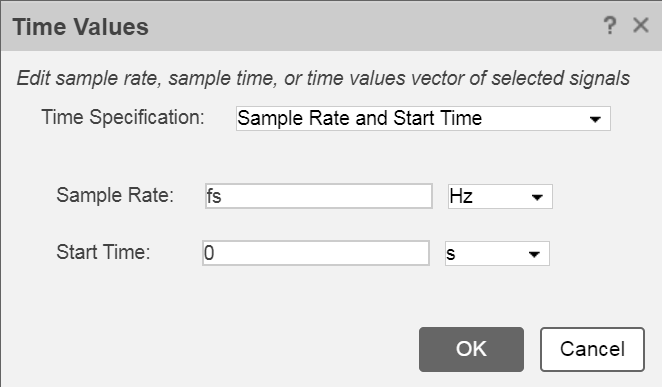

Отразим спектр сигнала. Для этого перейдём на вкладку **DISPLAY**, и нажмём на пиктограмму **Spectrum**. Добавим курсор данных. Для этого выберем в выпадающем меню **Data Cursors** опцию **One**. Определим граничную частоту, выше которой уровень шума явно превышает уровень полезного сигнала.

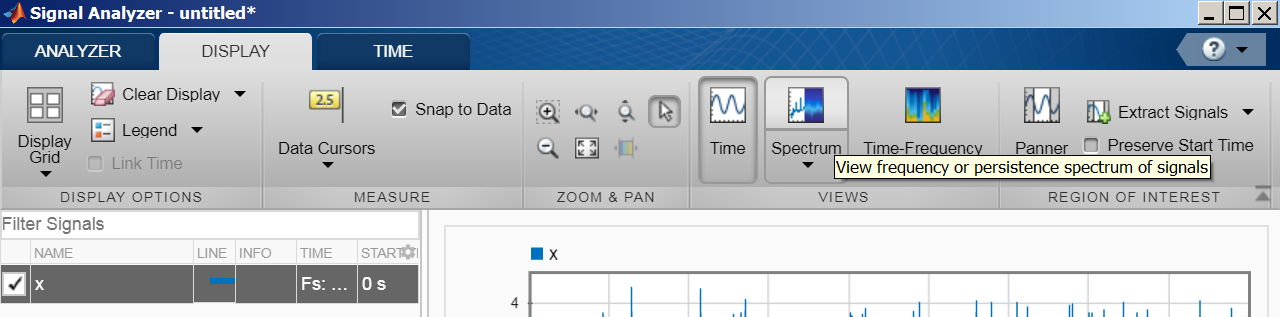

asfasfsafas

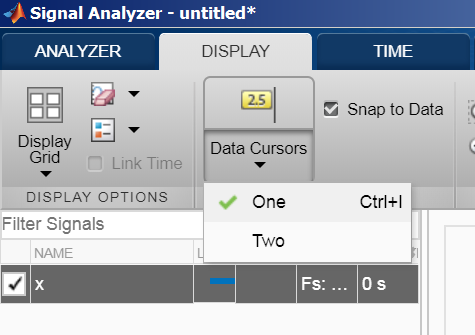            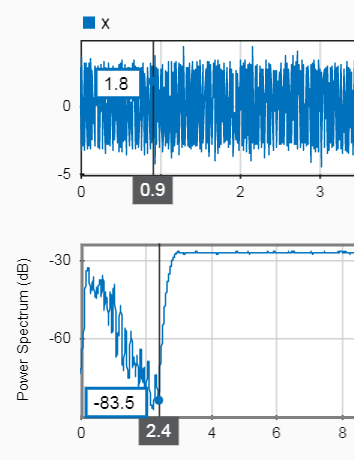

Перед анализом сигнала полезно сделать его копию, чтобы у нас была возможность наглядно сравнивать результаты до и после обработки. Для этого нужно кликнуть по нашему вектору *x* на панели доступных сигналов правой кнопкой мыши и выбрать опцию **Duplicate**. Копия сигнала *x_Copy* также отразится во временной и частотной областях, как только мы поставим галочку. 

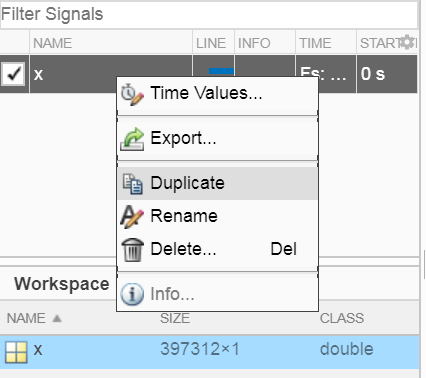

Теперь выполним операцию фильтрации. Перейдём на вкладку **ANALYZER** и нажмём на пиктограмму **Lowpass**. Откроется меню параметров фильтра нижних частот. Укажем параметры фильтра - частоту среза, крутизну срезу, подавление в полосе заграждения. Удостоверимся, что выбран именно сигнал *x_Copy* и нажмём кнопку **Lowpass**.

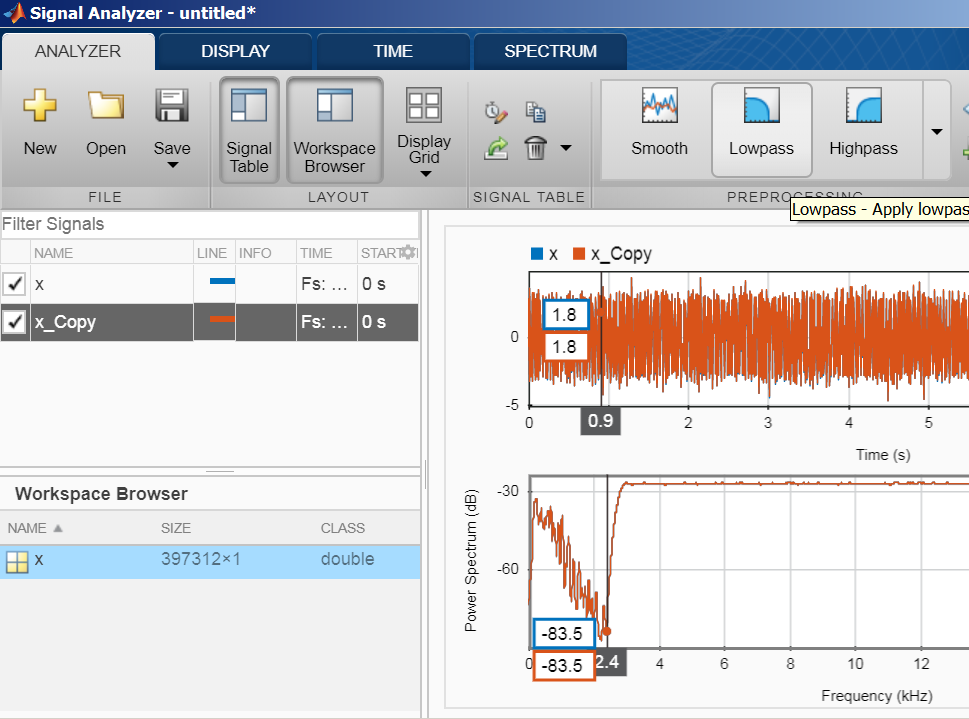    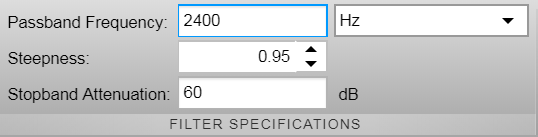

Мы тут же можем визуально оценить влияние фильтра нижних частот на наш сигнал, а также экспортировать обработанный сигнал (*x_Copy*) в рабочее пространство MATLAB.

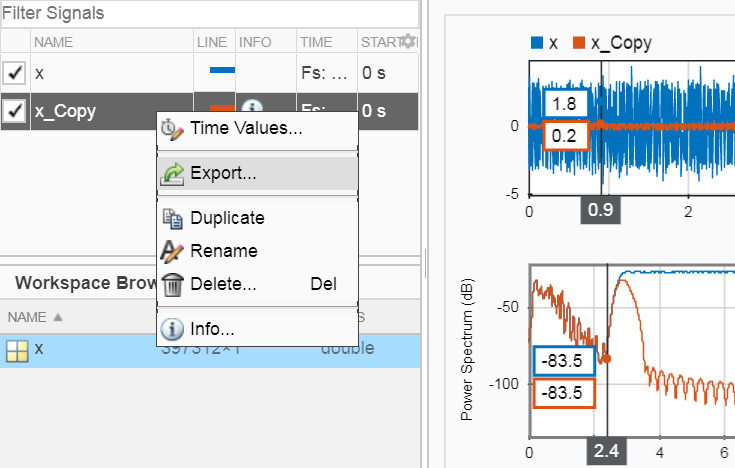

После экспорта мы просто свернём приложение **Signal Analyzer.**

Прослушаем вектор *x_Copy* командой *sound*.

sound(x_Copy,fs);

## Построение графика спектральной плотности мощности

Мы можем получить значения спектральной плотности мощности (СПМ) сигнала в виде численного вектора при помощи функции *periodogram*. Сохраним отсчёты СПМ сигнала *х* в переменную *pxx*, вектор значений частоты - в переменную *fx*. Отразим зависимость на графике.

[pxx,fx] = periodogram(x,[],[],fs);
logpxx = 10*log10(pxx);
plot(fx,logpxx);
grid on;
hold on;
xline(2500,'r--');

## Разработка цифрового фильтра в Filter Designer App

Приложение Filter Designer позволяет нам создавать различные цифровые фильтры. Разработанные фильтры хранятся в рабочем пространстве в виде объектов фильтров или в виде численых значений коэффициентов их передаточной функции. Воспользуемся этим приложением для создания фильтра нижних частот. 

filterDesigner;

Создадим фильтр нижних частот, отделяющий полезный сигнал от помехи. Выберем тип фильтра - FIR Equiripple (фильтр с конечной импульсной характеристикой, или КИХ-филбтр). Порядок разрабатываемого фильтра будет минимальный, при котором мы будем иметь устраивающую нас АЧХ. 

Опишем АЧХ, указав частотные и амплитудные характеристики - частоту дискретизации, границу полосы пропускания и начало полосы заграждения (пункт 1 на рисунке), уровень пульсаций в полосе пропускаяния и аттенюацию в полосе заграждения (пункт 2 на рисунке). Далее просто нажмём Design Filter (пункт 3 на рисунке), и убедимся, что АЧХ разработанного фильтра подходит для решаемой задачи.

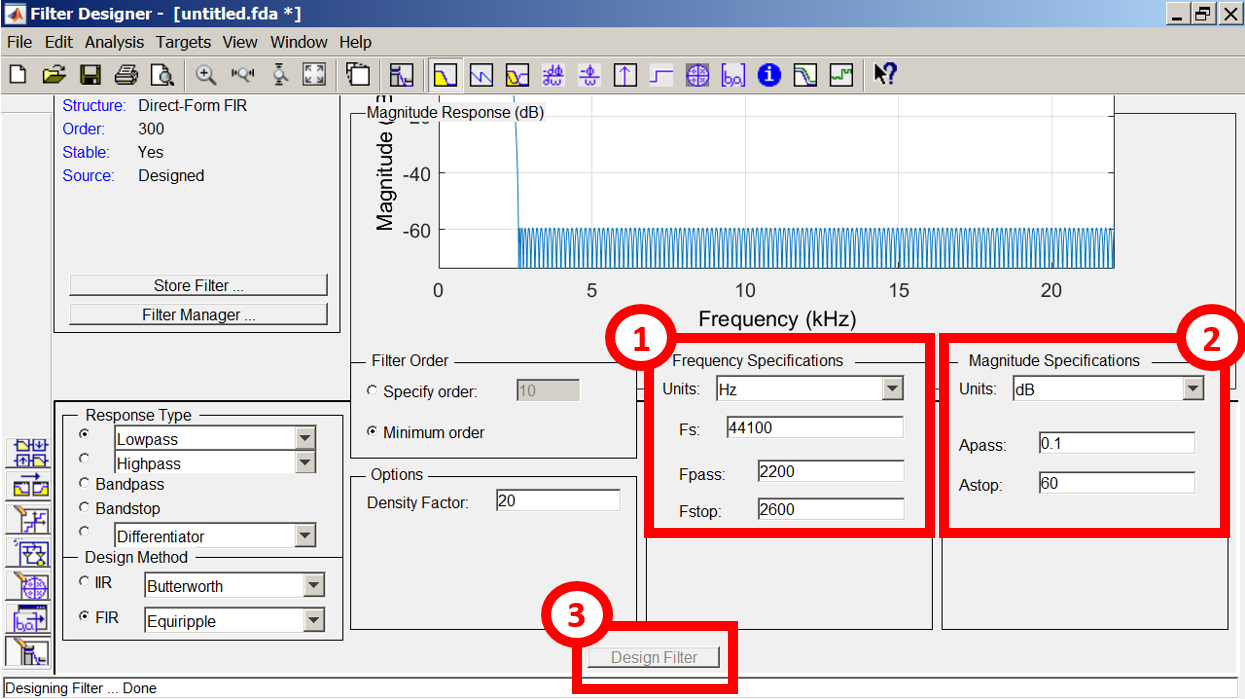

Экспортируем разработанный фильтр в рабочее пространство MATLAB в виде коэффициентов числителя передаточной функции - Num (у КИХ-фильтров единственный коэффициент знаменателя передаточной функции, и он равен единице).

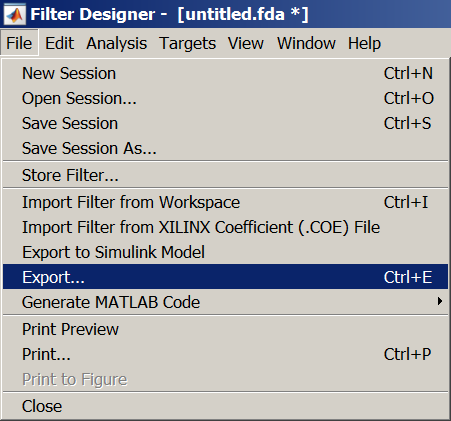       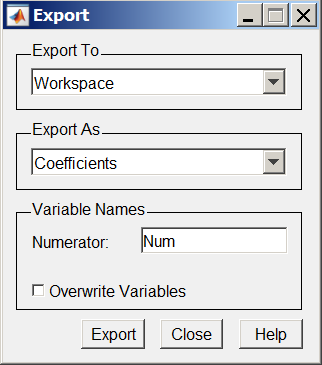

Или же загрузите коэффициенты из mat-файла:

% load lowpass;

## Фильтрация сигнала

Осуществим фильтрацию сигнала *x* разработанным фильтром. Передадим команде *filter* коэффициенты числителя передаточной функции, один коэффициент знаменателя, равный 1, и сигнал *x*. Отфильтрованный сигнал запишем в перменную *y*.

y = filter(Num,1,x);

## Визуализация результатов обработки

Добавим сигнал *y* для визуализации в Signal Analyzer. Укажем ему значения времени - частоту дискретизации. 

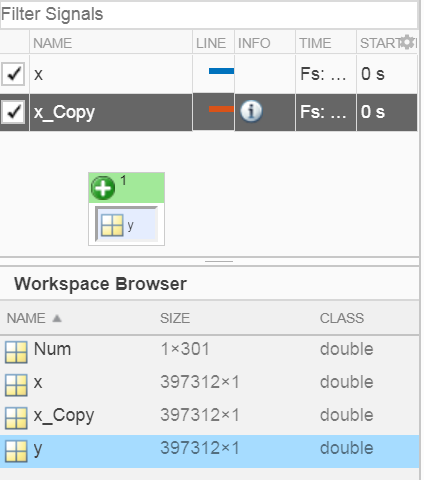

Теперь отрисуем СПМ сигнала *у* на одном графике с СПМ сигнала *х*.

[pxy,fy] = periodogram(y,[],[],fs);
logpxy = 10*log10(pxy);
plot(fx,logpxy);
hold off;

И прослушаем отфильтрованный сигнал* y *командой* sound*.

sound(y,fs);